# PHYS 4030 Homework 3: PCA Lab

**Name: **Johannes Irnawan

**ID:** 215 010 960

In this homework, a set of data will be used for Principal Component Analysis practice. PCA is often used to simplify data, reduce noise, and find unmeasured "latent variables". The set of data that willl be used is "speed_dating.csv". 

# Loading and Cleaning up Data

Before we start, the memory has to be cleared. This frees up memory space to be used for the lab.

% Clearing up the memory:
clear; clf;

The data is then loaded into MATLAB as a table. To clear up the data, the file is read as an array instead. There are two cases for cleaning up the data:

- Remove the columns with more than 200 NaN's.

- Remove the rows with NaN's.

% Loading the Data into as a table:
data_table = readtable('speed_dating.csv','PreserveVariableNames',true);
% Cleaning the data using 'CleanMyTable.m':
data_clean = CleanMyTable(data_table,200);
head(data_clean)

ans = 8×24 table
    subject_id    wave    like_sports    like_tvsports    like_exercise    like_food    like_museums    like_art    like_hiking    like_gaming    like_clubbing    like_reading    like_tv    like_theater    like_movies    like_concerts    like_music    like_shopping    like_yoga    subjective_attractiveness    subjective_sincerity    subjective_intelligence    subjective_fun    subjective_ambition
    __________    ____    ___________    _____________    _____________    _______

# Visualize Some Preference Columns

Like the previous part, we want to see the correlation between the given preferences.

% Loading preference columns into a struct:
pref.tvsports = data_clean.like_tvsports;
pref.sports = data_clean.like_sports;
pref.museums = data_clean.like_museums;
pref.theater = data_clean.like_theater;
pref.shopping = data_clean.like_shopping;
head(struct2table(pref))

ans = 8×5 table
    tvsports    sports    museums    theater    shopping
    ________    ______    _______    _______    ________

       2           9         1          1           8   
       2           3         8          9           3   
       8           3         5          7           8   
       1           1         6          9           1   
       4           7         6          6           8   
       8          10         8          5           1   
       3           5        10         10          10   
       2           2         9          9           8   


The z-scores of the preference data set:

% Finding z-scores of each columns:
z_transform = (struct2array(pref) - mean(struct2array(pref)))./std(struct2array(pref));
z1.tvsports = z_transform(:,1);
z1.sports = z_transform(:,2);
z1.museums = z_transform(:,3);
z1.theater = z_transform(:,4);
z1.shopping = z_transform(:,5);
% Showing the first 8 rows as table:
head(struct2table(z1))

ans = 8×5 table
    tvsports     sports     museums     theater     shopping
    ________    ________    ________    ________    ________

    -0.91194     0.99162     -2.9323     -2.5585     0.91241
    -0.91194     -1.2906     0.49716     0.98467    -0.99991
      1.2293     -1.2906    -0.97263    0.098875     0.91241
     -1.2688     -2.0513     -0.4827     0.98467     -1.7648
    -0.19819     0.23089     -0.4827    -0.34402     0.91241
      1.2293       1.372     0.49716    -0.78692     -1.7648
    -0.55506    -0.52985       1.477      1.4276      1.6773
    -0.91194      -1.671     0.98709     0.98467     0.91241


Pairplots of the given preferences:

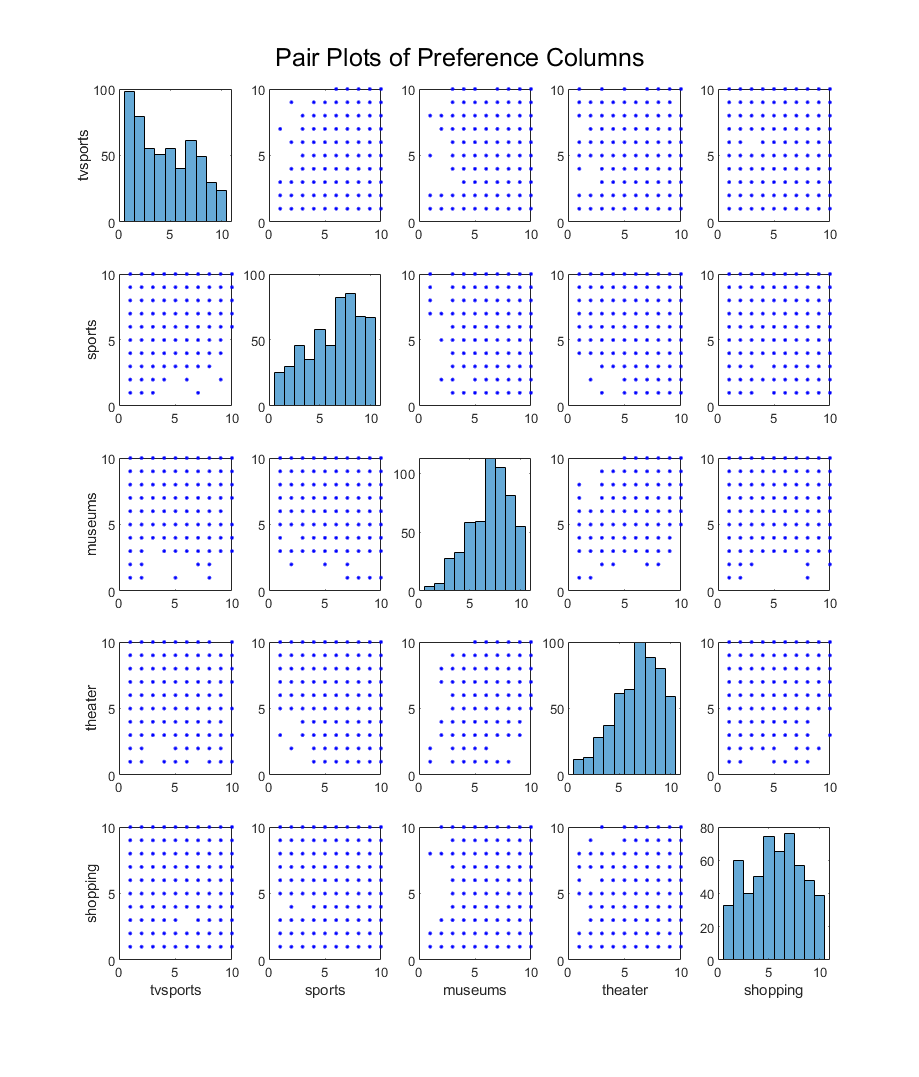

% To make plotting easy, the table can be saved as array:
z_array = struct2array(pref);
z_label = ["tvsports" "sports" "museums" "theater" "shopping"];
% Plotting the preference columns:
clf; figure();
figure_1 = figure('Position', [100, 100, 1024, 1200]);
for n_column = 1:5
    for n_row = 1:5
        subplot(5,5,(n_column - 1)*5 + n_row)
        if n_row == n_column
            histogram(z_array(:,n_row))
        else
            plot(z_array(:,n_row),z_array(:,n_column),'b.')
        end
        if n_row == 1
            ylabel(z_label(n_column))
        end
        if n_column == 5
            xlabel(z_label(n_row))
        end
    end
end
sgtitle('Pair Plots of Preference Columns')

The heatmap of the preference column:

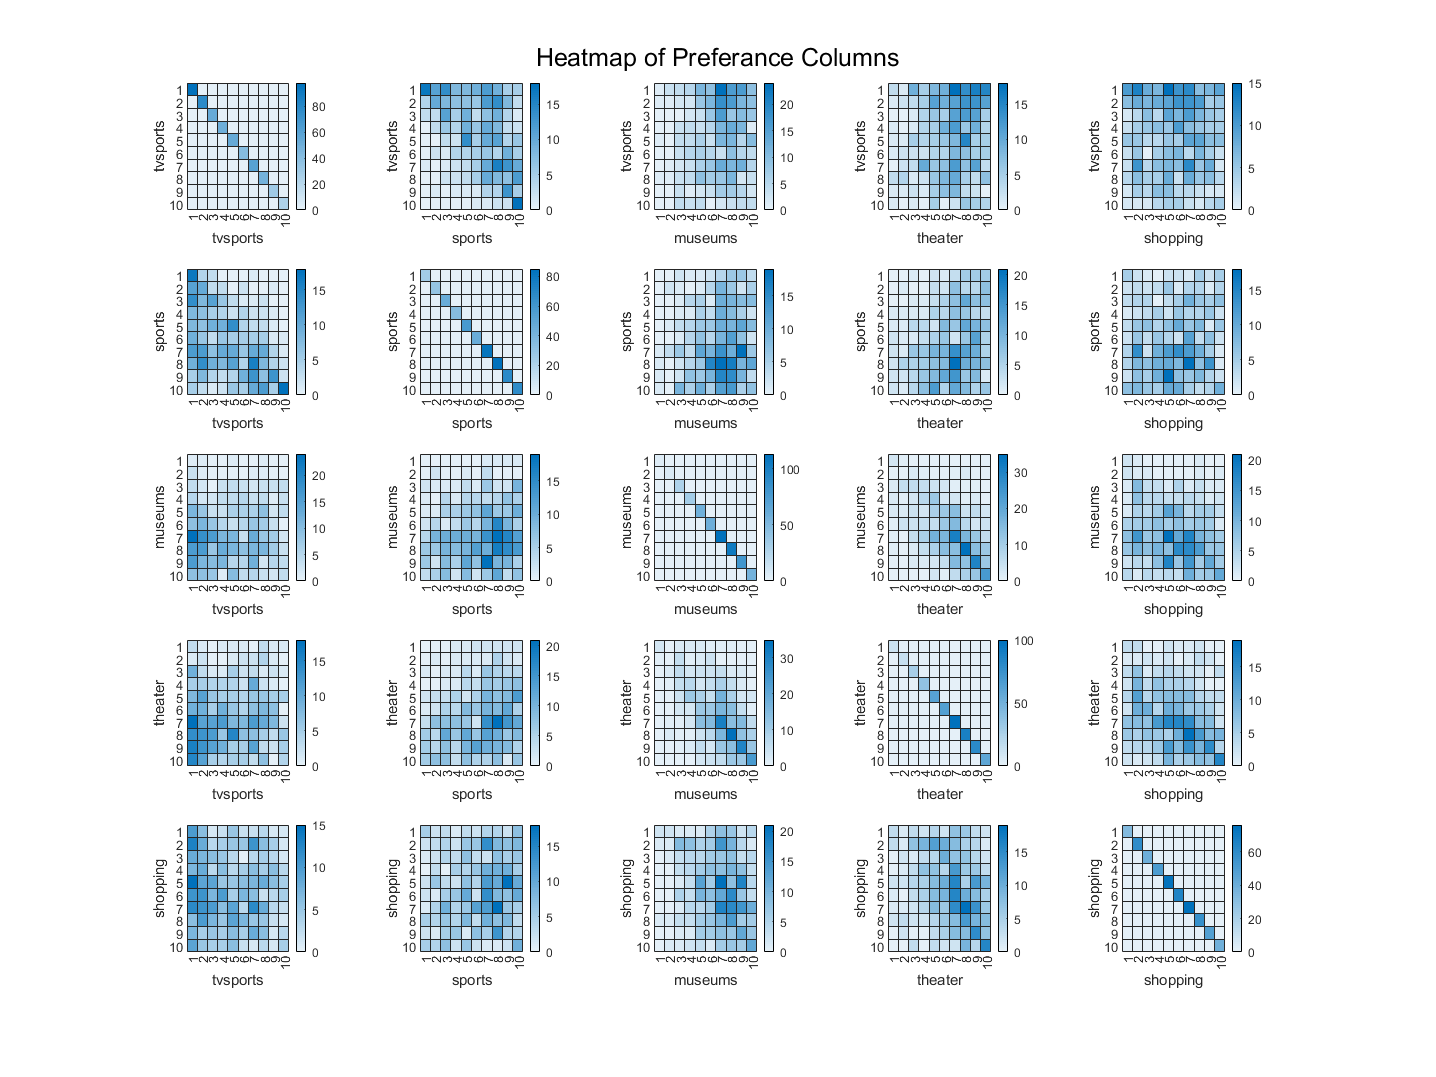

% Plotting heatmap:
clf; figure();
figure_1 = figure('Position', [100, 100, 1600, 1200]);
for n_column = 1:5
    for n_row = 1:5
        subplot(5,5,(n_column - 1)*5 + n_row)
        h = heatmap(struct2table(pref),z_label(n_row),z_label(n_column));
        h.Title = [];
    end
end
sgtitle('Heatmap of Preferance Columns');

Looking at the heatmap, the results make sense intuitively. Some correlation that I may expect is the preference of sports and tv sports, which is shown to be correlated. Another correlation I would expect is the preference of museums and theater, which is also shown to be correlated.

# Fitting PCA on Preference Data

First step to fitting PCA on the preference data is to find the eigenvalues and the eigenvectors of the preference data. However, since the data set is not square matrix, we can use correlation coefficient to find the correlation matrix and use it to find the eigenvalues and eigenvectors.

% Finding eigenvalues and eigenvectors of pref:
pref_corr = corrcoef(struct2array(z1));
[eigen.vector,eigen.value] = eig(pref_corr);
% Sorting the eigenvalues and eigenvectors:
[val,n] = sort(diag(eigen.value));
eigen.value = eigen.value(n,n);
eigen.vector = eigen.vector(:,n);
struct2table(eigen)

ans = 5×2 table
                                   vector                                                          value                       
    ____________________________________________________________________    ___________________________________________________

     0.29542        0.62245    -2.0805e-05       -0.64992       -0.32075    0.40886          0          0          0          0
    -0.40057       -0.58749        0.16031       -0.53219       -0.43067          0    0.52001          0          0          0
      0.5569       -0.33823        0.45491       -0.32413        0.51329          0          0    0.82166          0          0
    -0.66322        0.33335        0.22422       -0.26506        0.57313          0          0          0     1.3412          0
    0.047721       -0.20466       -0.84681       -0.34504        0.34597          0          0          0          0     1.9083


Now that we have the eigenvalues and the eigenvectors in ascending order, we can compute the PCA using the top 3 eigenvectors. These eigenvectors are used as the projection matrix.

% Taking the top 3 eigenvector:
eigen.vect2 = [eigen.vector(:,end),eigen.vector(:,end-1),eigen.vector(:,end-2)];

To get the transformed 2D Z matrix, we take the dot product of X and W, which are the preference data and the top 3 eigenvectors respectively.

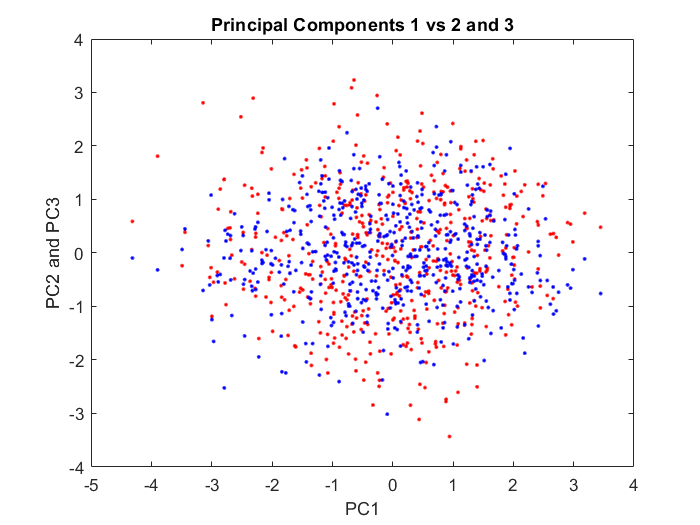

% Taking the dot product of X and W:
% For a dot product of a matrix and vector, MATLAB's built in command is
% NOT a good way to do dot product:
for k = 1:length(eigen.vect2(1,:))
    for n = 1:length(z_transform(:,1))
        for m = 1:length(z_transform(1,:))
            comp(m) = z_transform(n,m)*eigen.vect2(m,k);
        end
        PComp(n,k) = sum(comp);
    end
end
% Plotting the PC against each other to show uncorrelation:
clf; figure();
plot(PComp(:,1),PComp(:,2),'r.',PComp(:,1),PComp(:,3),'b.');
title('Principal Components 1 vs 2 and 3');
xlabel('PC1'), ylabel('PC2 and PC3')

We can see from the plot above that the principal component 1 is not correlated to principal component 2 and 3.

# Use PCA for Dimensionality Reduction

We are going to predict if a user likes to read. The first step we can do is to plot the original preferences against reading. First, we can plot the heatmap of the originals vs reading, and then use scatter plot and linear regression to see if there is a correlation. We can compare the linear regression against the heatmap and see if they make sense intuitively.

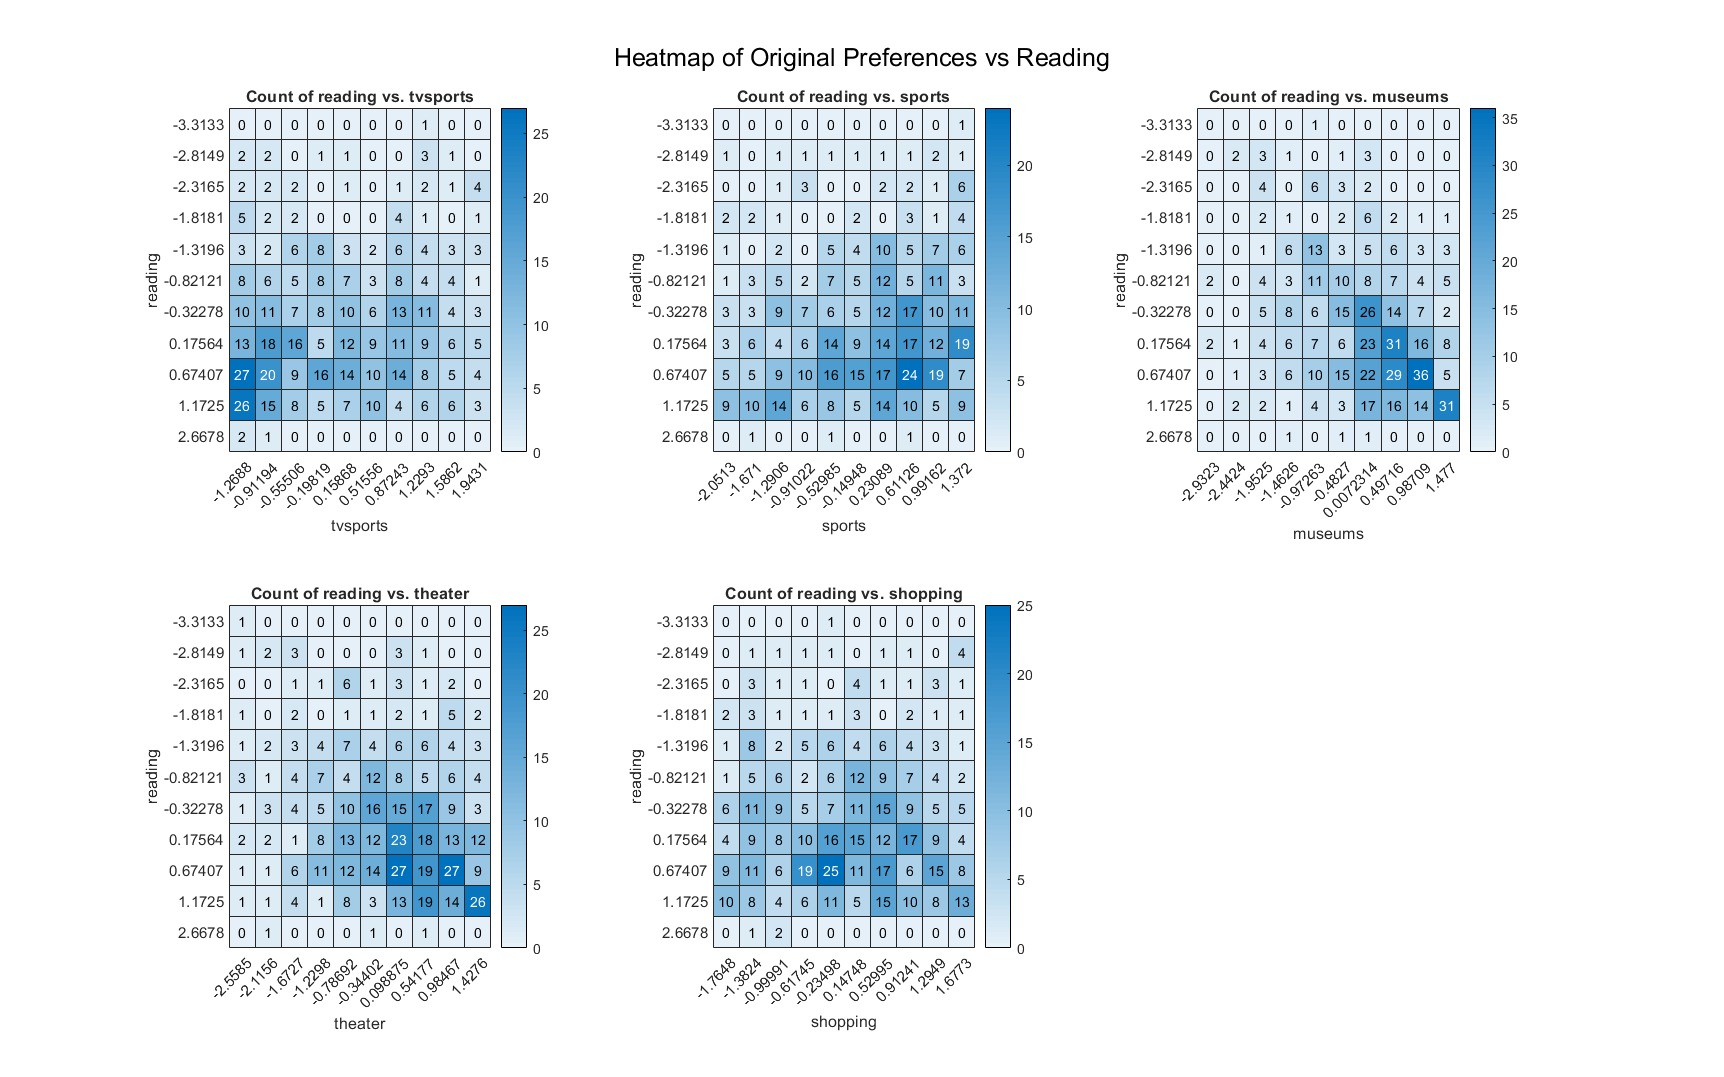

% Putting reading preference into MATLAB:
pref.reading = data_clean.like_reading;
z1.reading = (pref.reading - mean(pref.reading))/std(pref.reading);
% Plotting original variables against reading preference (heatmap):
clf; figure();
figure_1 = figure('Position', [100, 100, 1600, 1000]);
for n = 1:5
    subplot(2,3,n)
    heatmap(struct2table(z1),z_label(n),'reading')
end
sgtitle('Heatmap of Original Preferences vs Reading')

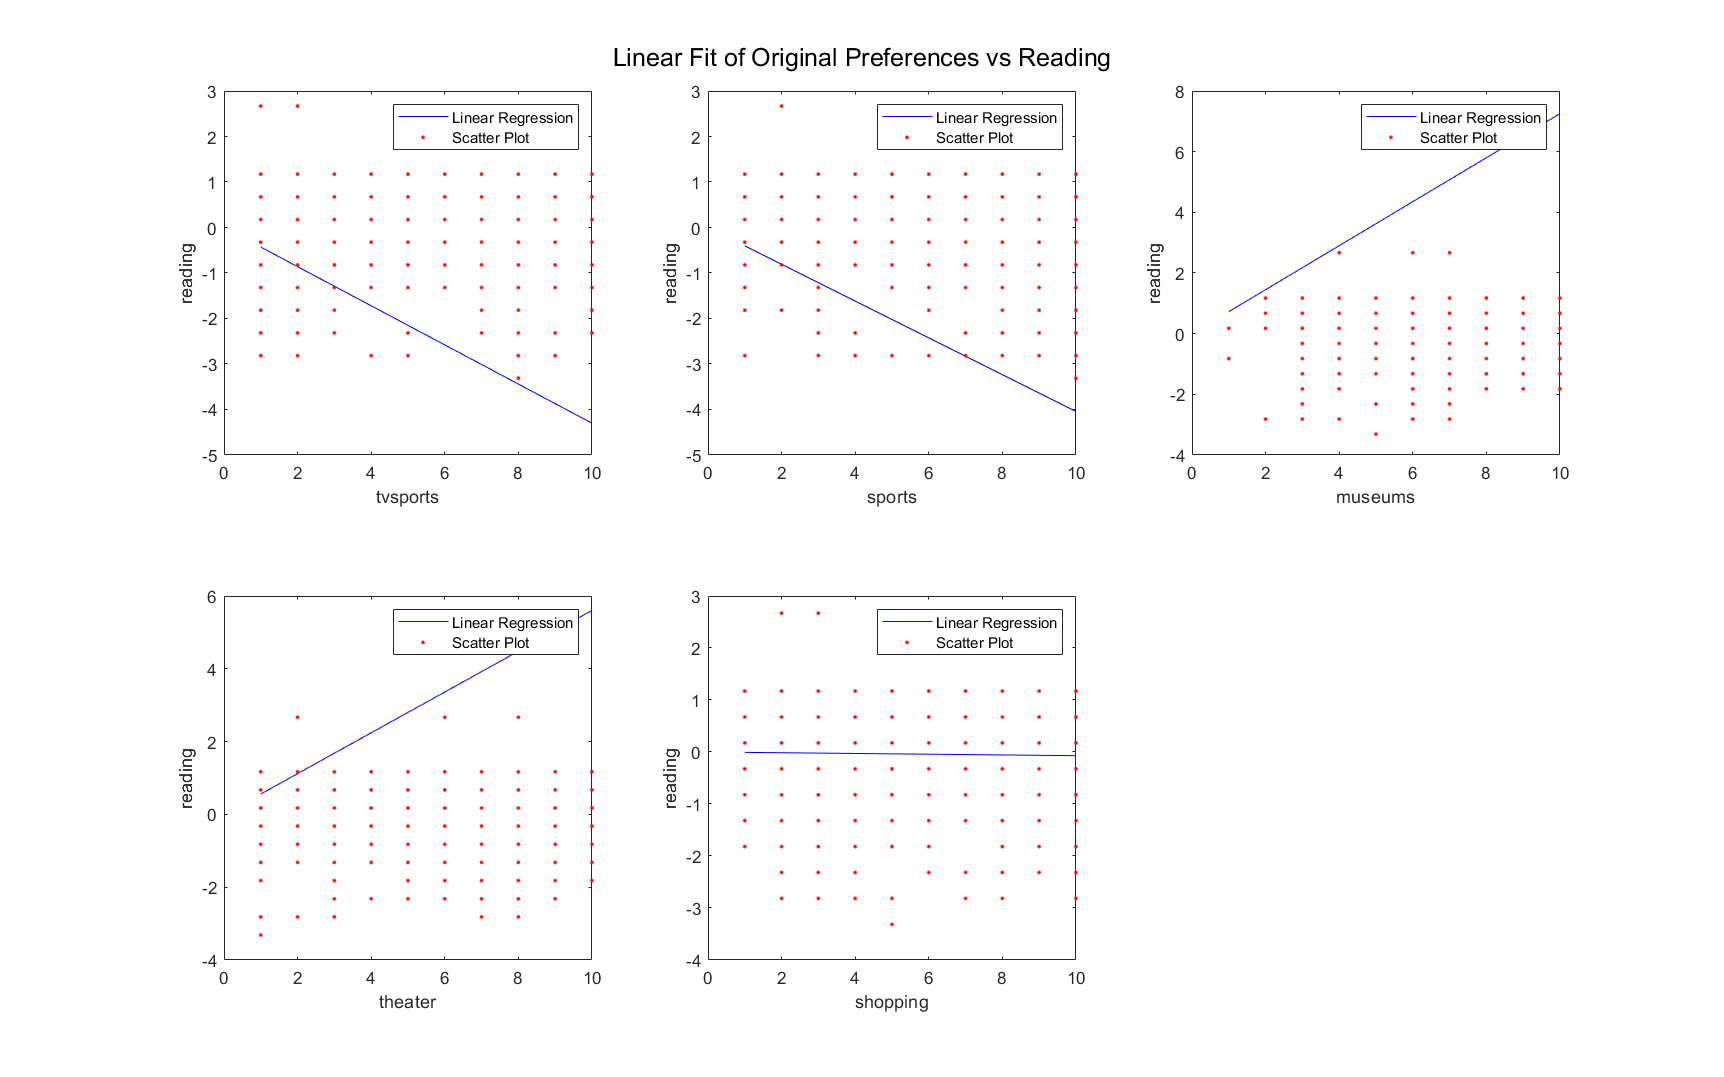

% Plotting original variables against reading preference (line fit):
clf; figure();
figure_1 = figure('Position', [100, 100, 1600, 1000]);
X = [ones(length(z1.reading),1) z_array];
line_reg = crossval('mse',X,z1.reading,'Predfun',@regf);
for n = 1:5
    subplot(2,3,n)
    plot(z_array(:,n),z_array(:,n)*regress(z_array(:,n),z1.reading), ...
        'b-',z_array(:,n),z1.reading,'r.')
    legend('Linear Regression','Scatter Plot')
    xlabel(z_label(n)), ylabel('reading')
end
sgtitle('Linear Fit of Original Preferences vs Reading')

fprintf('The Mean Crossval is %f',line_reg)

The Mean Crossval is 0.863435

Intuitively, the slope of the regression line makes sense when comparing to the heatmap. For example, the chances that someone would like museums increases as they like reading, and this is shown in both the linear regression and the heatmap.

Next, we can compare reading to the Principal Component 1.

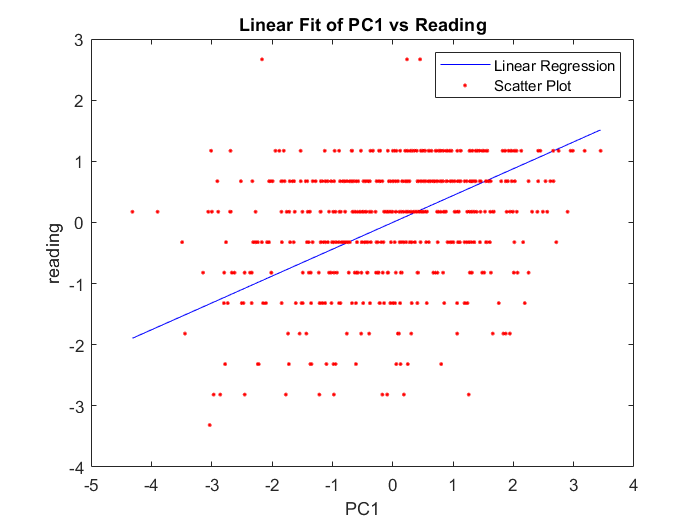

% Plotting PC against reading:
clf; figure();
X = [ones(length(z1.reading),1) PComp(:,1)];
line_reg = crossval('mse',X,z1.reading,'Predfun',@regf);
plot(PComp(:,1),PComp(:,1)*regress(PComp(:,1),z1.reading),'b-',PComp(:,1),z1.reading,'r.')
legend('Linear Regression','Scatter Plot')
xlabel('PC1'), ylabel('reading')
title('Linear Fit of PC1 vs Reading')

fprintf('The Mean Crossval is %f',line_reg)

The Mean Crossval is 0.900624

Next, we can compare reading to all Principal Components.

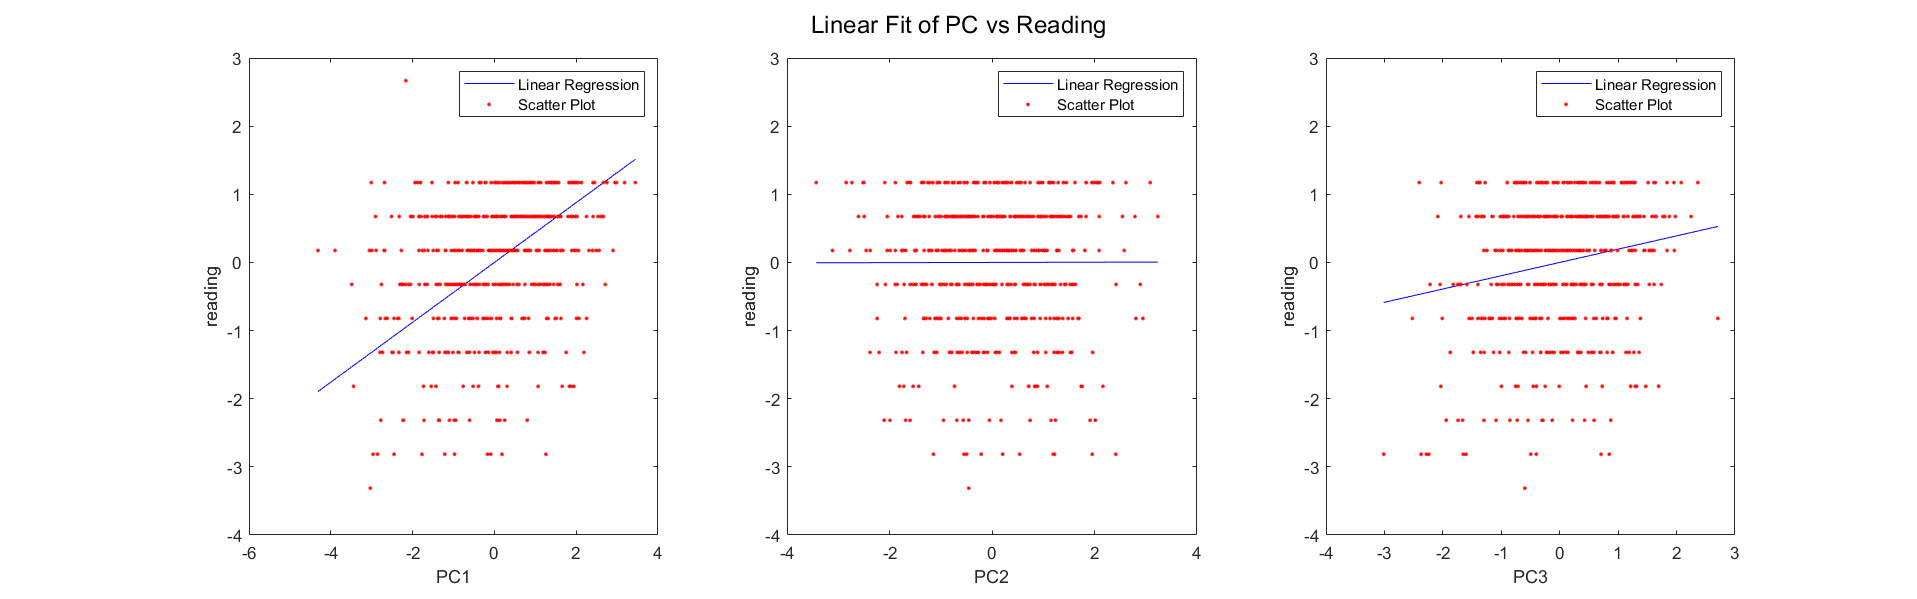

% Plotting PC against reading:
clf; figure();
figure_1 = figure('Position', [100, 100, 1600, 500]);
X = [ones(length(z1.reading),1) PComp];
line_reg = crossval('mse',X,z1.reading,'Predfun',@regf);
for n = 1:3
    subplot(1,3,n)
    plot(PComp(:,n),PComp(:,n)*regress(PComp(:,n),z1.reading),'b-',PComp(:,n),z1.reading,'r.')
    legend('Linear Regression','Scatter Plot')
    xlabel(['PC' num2str(n)]), ylabel('reading')
end
sgtitle('Linear Fit of PC vs Reading')

fprintf('The Mean Crossval is %f',line_reg)

The Mean Crossval is 0.873343